s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gp=10^6/(s*(s+500))

Gp =
 
     1e06
  -----------
  s^2 + 500 s
 
Continuous-time transfer function.




zpk(Gp)

ans =
 
    1e+06
  ---------
  s (s+500)
 
Continuous-time zero/pole/gain model.




Gs=1

Gs = 1

Gr=1

Gr = 1

Ga=3

Ga = 3

Gf=0.5

Gf = 0.5000

kc=4

kc = 4


wc=1000

wc = 1000

Tp0=1.024

Tp0 = 1.0240

Sp0=1.33

Sp0 = 1.3300


PI=1+s/10

PI =
 
  s + 10
  ------
    10
 
Continuous-time transfer function.



Rd=(1+s/10^3)/(1+s/(3*10^3))

Rd =
 
  3000 s + 3e06
  -------------
  1000 s + 3e06
 
Continuous-time transfer function.



L=kc/s*Gf*Gs*Ga*Gp*PI*Rd*Rd

L =
 
  5.4e13 s^3 + 1.085e17 s^2 + 5.508e19 s + 5.4e20
  -----------------------------------------------
  1e07 s^5 + 6.5e10 s^4 + 1.2e14 s^3 + 4.5e16 s^2
 
Continuous-time transfer function.



Gc=kc/s*PI*Rd*Rd

zpk(L)

ans =
 
  5.4e06 (s+1000)^2 (s+10)
  ------------------------
   s^2 (s+3000)^2 (s+500)
 
Continuous-time zero/pole/gain model.



omega=logspace(0,10,6000)

omega = 	1.0e+04 *

    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


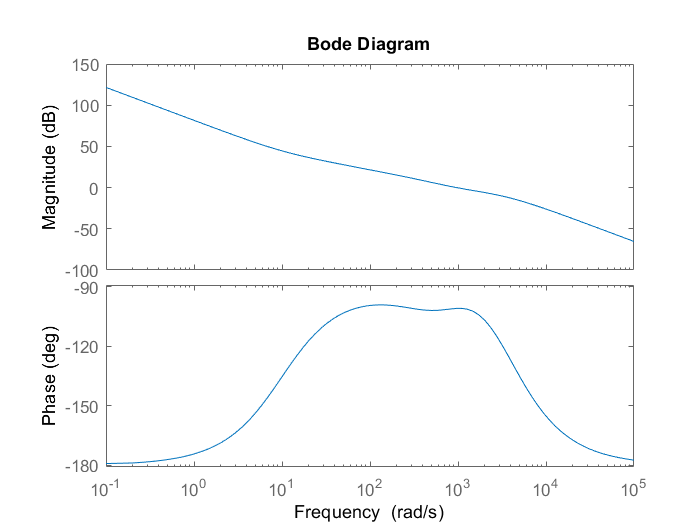


bode(L)

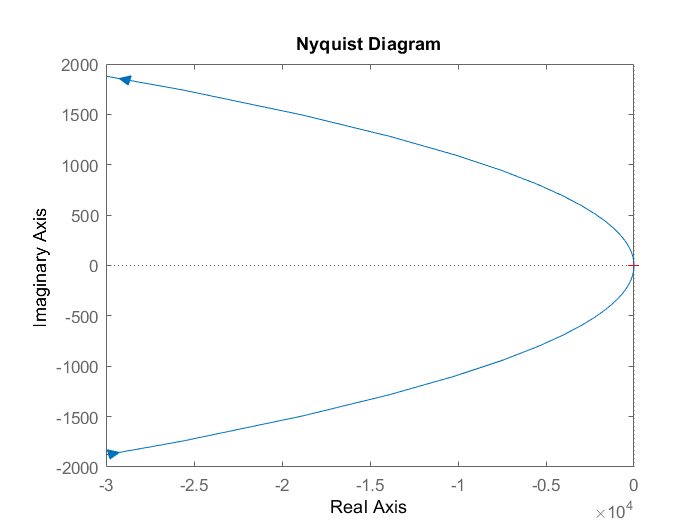

nyquist(L)

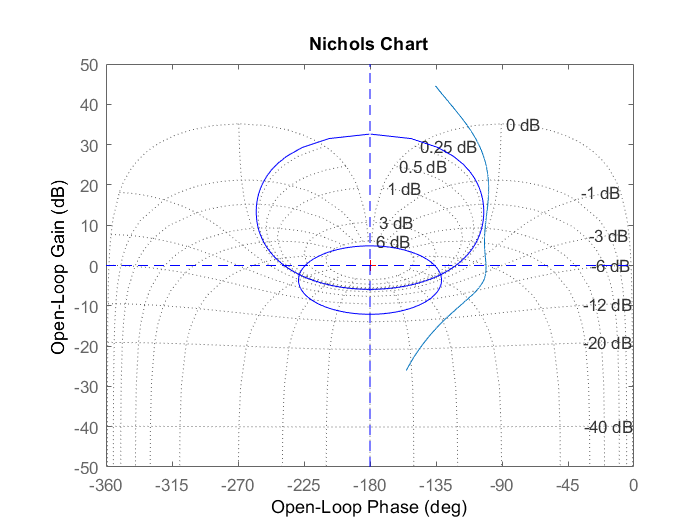


nichols(L,omega)
hold on
grid on
myngridst(Tp0,Sp0)
hold off

controlSystemDesigner(Gp,Gc,1,0.5)
